## Full System:


$$R_{growth}=  (\psi_g + \psi_d)\cdot\frac{(\eta_AA + 1)^4 + \left(\frac{P_R}{\delta}\right)^4}{(\eta_B B_{ext} + 1)(\eta_AA+ 1)^4+ \left( \frac{P_R}{\delta} \right)^4 } - \psi_d-\psi_C \cdot \frac{\eta_{I} I \cdot  \left(\frac{P_C}{\delta}\right)^2}{\eta_{I}I \cdot \left(\frac{P_C}{\delta}\right)^2+(\eta_AA +1)^2} $$



$$\frac{\mathrm{dy}}{\mathrm{dt}}=R_{\mathrm{growth}\;} \cdot y\left(1-y\right)$$


clear all; close all
addpath('./MatlabFuncs/')

xdata = [0, .2, .5, 1, 2, 5, 10, 20, 50, 100];

dataTable = readtable('FittingData\mean_std.xlsx');

y_data = table2array(dataTable);
y_data = y_data(1:4, 2:end);

% Converting y to growth rate
Y0 = 1/12; K = 1; t=96;
r_data = revLogest(y_data, Y0, K, t);
disp(r_data);

    0.0711    0.0743    0.0786    0.0791    0.0778    0.0766    0.0799    0.0802    0.0740    0.0687
   -0.0055   -0.0001    0.0036    0.0077    0.0115    0.0320    0.0500    0.0644    0.0731    0.0599
    0.0779    0.0732    0.0736    0.0751    0.0757    0.0703    0.0542    0.0236   -0.0110   -0.0213
   -0.0040    0.0023    0.0022    0.0055    0.0104    0.0168    0.0020   -0.0055   -0.0168   -0.0212



r_diff = r_data(1, :) - mean(r_data(1, :));
r_norm = r_data - r_diff;
disp(r_norm);

    0.0760    0.0760    0.0760    0.0760    0.0760    0.0760    0.0760    0.0760    0.0760    0.0760
   -0.0006    0.0017    0.0010    0.0047    0.0098    0.0315    0.0461    0.0603    0.0752    0.0672
    0.0828    0.0750    0.0710    0.0720    0.0740    0.0698    0.0503    0.0194   -0.0090   -0.0140
    0.0010    0.0041   -0.0004    0.0024    0.0087    0.0162   -0.0019   -0.0096   -0.0147   -0.0139



y_norm = endLogest(r_norm, Y0, 1, t);
disp(y_norm);

    0.9919    0.9919    0.9919    0.9919    0.9919    0.9919    0.9919    0.9919    0.9919    0.9919
    0.0730    0.0893    0.0837    0.1152    0.1754    0.6311    0.8749    0.9645    0.9913    0.9814
    0.9958    0.9911    0.9870    0.9882    0.9902    0.9854    0.9122    0.3501    0.0340    0.0212
    0.0838    0.1100    0.0743    0.0949    0.1610    0.2832    0.0650    0.0320    0.0198    0.0214



eta_A = 1/0.76;

rate_func2 = @(x,xdata)([
    ((x(1) + x(5)) .* transReduc(x, eta_A, xdata)) - x(5);
    x(1)- x(3) .* apopActi(x, eta_A, xdata)
    ]);

rete_comb = @(x, xdata)(((x(1) + x(5)) .* transReduc(x, eta_A, xdata)) - x(5) - x(3) .* apopActi(x, eta_A, xdata));

options = optimoptions('lsqcurvefit','MaxFunctionEvaluations',100000, 'MaxIterations',40000); 
x0_both = [0.78, 1/0.76, .1, .1, 1, 5, 2];

lowerLim = repelem(0, length(x0_both));
upperLim = repelem(inf, length(x0_both));

[x_both, renorm_both, residual_both] = lsqcurvefit(rate_func2,x0_both,xdata,[r_norm(3, :); r_norm(2, :)],lowerLim,upperLim,options);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


MSE_both = mean((residual_both).^2,2); % mean percentage error
disp(x_both);

    0.0770    1.3158    0.0912    0.5847    0.0907    1.2869    2.5745



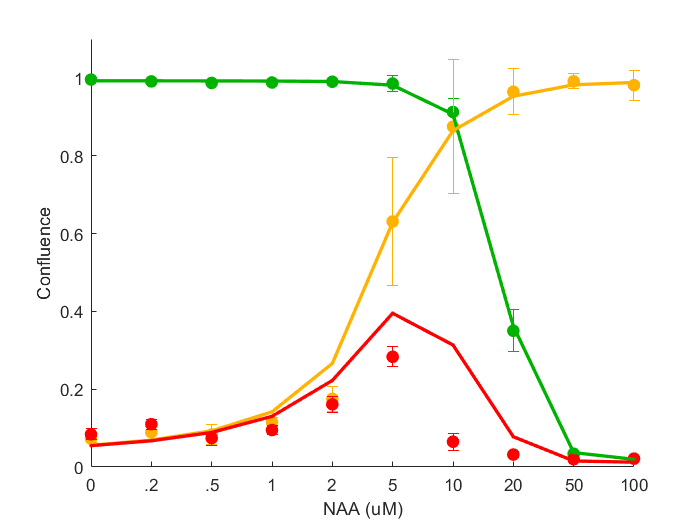

%%standard_dev
err1 = [0.002809344	0.005162316	0.004957646	0.001467934	0.002520465	0.019980023	0.033964324	0.054158992	0.002579971	0.000759584];
err2 = [0.010813322	0.018252794	0.026223576	0.012246634	0.031479622	0.16338727	0.171613373	0.059727441	0.01959887	0.03884396];
err3 = [0.014081056	0.012390267	0.020057457	0.012582435	0.020161014	0.025438707	0.021837773	0.007677594	0.004816866	0.00058251];


rpredict = [rate_func2(x_both, xdata); rete_comb(x_both, xdata)];
cpredict = endLogest(rpredict, Y0, 1, t);

fig = figure(1); clf(fig);

hold on;

e1 = errorbar([1:length(xdata)],y_norm(3, :),err1,'o','Color',[0,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[0,.7,0],'MarkerFaceColor',[0,.7,0]);
e2 = errorbar([1:length(xdata)],y_norm(2, :),err2,'o','Color',[1,.7,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,.7,0],'MarkerFaceColor',[1,.7,0]);
e3 = errorbar([1:length(xdata)],y_norm(4, :),err3,'o','Color',[1,0,0],'MarkerSize',7,...
    'MarkerEdgeColor',[1,0,0],'MarkerFaceColor',[1,0,0]);

p1 = plot([1:length(xdata)],cpredict(1,:),'.-','Color',[0,.7,0],'MarkerFaceColor',[0,.7,0],'LineWidth',2);
p2 = plot([1:length(xdata)],cpredict(2,:),'.-','Color',[1,.7,0],'MarkerFaceColor',[1,.7,0],'LineWidth',2);
p3 = plot([1:length(xdata)],cpredict(3,:),'.-','Color',[1, 0,0],'MarkerFaceColor',[1, 0,0],'LineWidth',2);

ylim([0, 1.1])
xticklabels({'0','.2','.5','1','2','5','10', '20', '50', '100'});
xlabel('NAA (uM)');
ylabel({'Confluence'});
gca.FontSize = 24;

box off;